%% Reduced-Channel Bandpower Features + SVM
% This script:
% 1. Loads the 7-channel epoch dataset
% 2. Extracts mu and beta power from every channel
% 3. Creates 14 understandable features
% 4. Trains a linear multiclass SVM
% 5. Evaluates classification accuracy
% 6. Measures the importance of every feature

clear;
close all;
clc;

%% Step 1: Set project path

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';


%% Step 2: Load the seven-channel epoch dataset

load(fullfile(basePath, 'Outputs', 'Filtered data', ...
    'combined_epochs_7channels.mat'));

disp('Seven-channel epoch data loaded.');

Seven-channel epoch data loaded.



disp(['Left data shape:  ', mat2str(size(all_left))]);

Left data shape:  [7 640 230]


disp(['Right data shape: ', mat2str(size(all_right))]);

Right data shape: [7 640 220]


disp(['Rest data shape:  ', mat2str(size(all_rest))]);

Rest data shape:  [7 640 420]




%% Step 3: Check the sampling rate

disp(['Sampling rate: ', num2str(samplingRate), ' Hz']);

Sampling rate: 160 Hz




%% Step 4: Balance the three classes

% The three classes may contain different numbers of epochs.
% Use the smallest class size so that every class has the same number.

numberOfEpochs = min([size(all_left,3), ...
                      size(all_right,3), ...
                      size(all_rest,3)]);

disp(['Balanced epochs per class: ', ...
    num2str(numberOfEpochs)]);

Balanced epochs per class: 220



% Keep the same random selections every time the code runs
rng(42);

% Randomly select epochs from each class
leftIndices = randperm(size(all_left,3), numberOfEpochs);
rightIndices = randperm(size(all_right,3), numberOfEpochs);
restIndices = randperm(size(all_rest,3), numberOfEpochs);

leftData = all_left(:,:,leftIndices);
rightData = all_right(:,:,rightIndices);
restData = all_rest(:,:,restIndices);


%% Step 5: Extract mu and beta features

% Each channel gives two features:
%
% Mu power   = 8–12 Hz
% Beta power = 13–30 Hz
%
% 7 channels × 2 features = 14 features

featuresLeft = extract_motor_bandpower(leftData, samplingRate);

featuresRight = extract_motor_bandpower(rightData, samplingRate);

featuresRest = extract_motor_bandpower(restData, samplingRate);

disp(['Left feature shape:  ', mat2str(size(featuresLeft))]);

Left feature shape:  [220 14]


disp(['Right feature shape: ', mat2str(size(featuresRight))]);

Right feature shape: [220 14]


disp(['Rest feature shape:  ', mat2str(size(featuresRest))]);

Rest feature shape:  [220 14]




%% Step 6: Create feature names

% Remove dots from PhysioNet channel names for easier display

cleanChannelNames = regexprep(string(selectedChannels), '\.', '');

numberOfChannels = length(cleanChannelNames);

featureNames = strings(1, numberOfChannels * 2);

for c = 1:numberOfChannels

    featureNames(2*c - 1) = cleanChannelNames(c) + "_mu";

    featureNames(2*c) = cleanChannelNames(c) + "_beta";

end

disp('Feature names:');

Feature names:


disp(featureNames');

    "FC3_mu"
    "FC3_beta"
    "C3_mu"
    "C3_beta"
    "CP3_mu"
    "CP3_beta"
    "Cz_mu"
    "Cz_beta"
    "FC4_mu"
    "FC4_beta"
    "C4_mu"
    "C4_beta"
    "CP4_mu"
    "CP4_beta"





%% Step 7: Combine all features

X = [featuresLeft;
     featuresRight;
     featuresRest];

% Create class labels
Y = [repmat("LEFT", numberOfEpochs, 1);
     repmat("RIGHT", numberOfEpochs, 1);
     repmat("REST", numberOfEpochs, 1)];

Y = categorical(Y);

disp(['Final feature matrix shape: ', mat2str(size(X))]);

Final feature matrix shape: [660 14]



% Expected shape:
% total epochs × 14 features


%% Step 8: Split the dataset into training and testing data

% Use 80% for training and 20% for testing

cv = cvpartition(Y, 'HoldOut', 0.20);

trainingIndices = training(cv);
testingIndices = test(cv);

XTrain = X(trainingIndices,:);
YTrain = Y(trainingIndices);

XTest = X(testingIndices,:);
YTest = Y(testingIndices);

disp(['Training samples: ', num2str(size(XTrain,1))]);

Training samples: 528


disp(['Testing samples:  ', num2str(size(XTest,1))]);

Testing samples:  132




%% Step 9: Create a linear SVM

% Linear SVM is easier to interpret than nonlinear kernels.

svmTemplate = templateSVM( ...
    'KernelFunction', 'linear', ...
    'Standardize', true);

svmModel = fitcecoc( ...
    XTrain, ...
    YTrain, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

disp('Linear multiclass SVM trained successfully.');

Linear multiclass SVM trained successfully.




%% Step 10: Test the SVM

predictedLabels = predict(svmModel, XTest);

accuracy = mean(predictedLabels == YTest) * 100;

fprintf('\nReduced-channel SVM accuracy: %.2f%%\n', accuracy);


Reduced-channel SVM accuracy: 45.45%


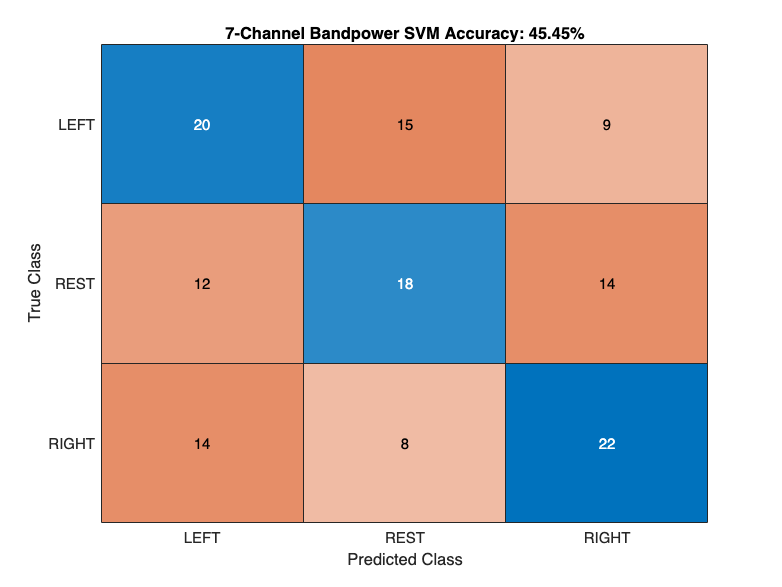



%% Step 11: Display the confusion matrix

figure;

confusionchart(YTest, predictedLabels);

title(['7-Channel Bandpower SVM Accuracy: ', ...
    num2str(accuracy, '%.2f'), '%']);



%% Step 12: Calculate feature importance

% Permutation importance:
%
% Shuffle one feature at a time.
% If accuracy decreases strongly, that feature is important.

originalAccuracy = mean(predictedLabels == YTest);

featureImportance = zeros(1, size(XTest,2));

for f = 1:size(XTest,2)

    shuffledTestData = XTest;

    % Shuffle only the current feature
    shuffledTestData(:,f) = ...
        shuffledTestData(randperm(size(XTest,1)), f);

    shuffledPredictions = predict( ...
        svmModel, shuffledTestData);

    shuffledAccuracy = mean( ...
        shuffledPredictions == YTest);

    % Accuracy decrease caused by shuffling the feature
    featureImportance(f) = ...
        originalAccuracy - shuffledAccuracy;

end


%% Step 13: Display feature importance table

importanceTable = table( ...
    featureNames', ...
    featureImportance', ...
    'VariableNames', ...
    {'Feature', 'AccuracyDecrease'});

importanceTable = sortrows( ...
    importanceTable, ...
    'AccuracyDecrease', ...
    'descend');

disp('Feature importance:');

Feature importance:


disp(importanceTable);

     Feature      AccuracyDecrease
    __________    ________________

    "CP3_beta"          0.12121   
    "C3_mu"             0.10606   
    "C4_beta"          0.098485   
    "CP3_mu"           0.090909   
    "FC3_mu"           0.075758   
    "Cz_mu"            0.075758   
    "FC4_mu"           0.068182   
    "C3_beta"           0.05303   
    "CP4_mu"            0.05303   
    "FC4_beta"         0.045455   
    "CP4_beta"         0.030303   
    "C4_mu"                   0   
    "FC3_beta"       -0.0075758   
    "Cz_beta"         -0.030303   



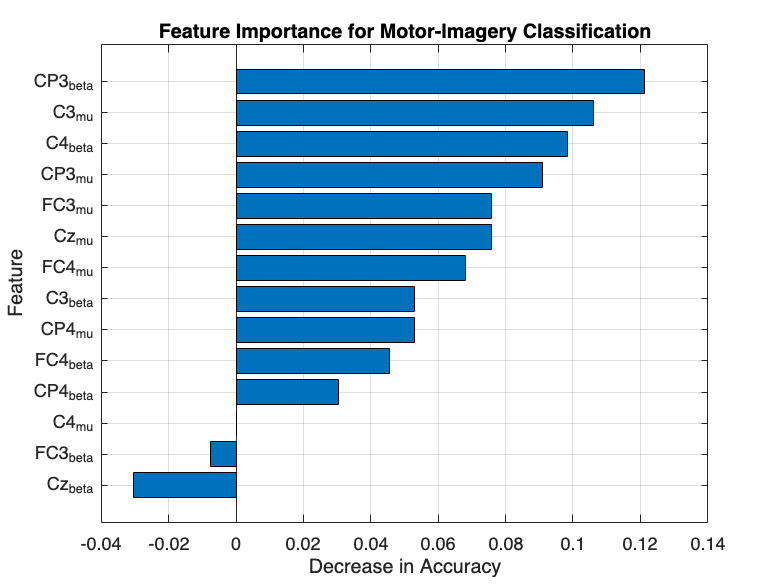



%% Step 14: Plot feature importance

figure;

barh(importanceTable.AccuracyDecrease);

yticks(1:height(importanceTable));

yticklabels(importanceTable.Feature);

set(gca, 'YDir', 'reverse');

xlabel('Decrease in Accuracy');

ylabel('Feature');

title('Feature Importance for Motor-Imagery Classification');

grid on;



%% Step 15: Save the model and results

save(fullfile(basePath, 'Outputs', ...
    'reduced_channel_bandpower_svm.mat'), ...
    'svmModel', ...
    'accuracy', ...
    'featureNames', ...
    'featureImportance', ...
    'importanceTable', ...
    'selectedChannels', ...
    'samplingRate');

disp('Reduced-channel SVM model saved successfully.');

Reduced-channel SVM model saved successfully.




%% Local Function: Extract Mu and Beta Bandpower


function features = extract_motor_bandpower(data, samplingRate)

    % Data shape:
    % channels × time points × epochs

    numberOfChannels = size(data,1);
    numberOfEpochs = size(data,3);

    % Two features per channel:
    % mu power and beta power

    numberOfFeatures = numberOfChannels * 2;

    features = zeros(numberOfEpochs, numberOfFeatures);

    for e = 1:numberOfEpochs

        featurePosition = 1;

        for c = 1:numberOfChannels

            % Get one EEG signal:
            % one channel from one epoch

            signal = double(data(c,:,e));

            % Calculate power spectral density

            [powerSpectrum, frequencies] = ...
                pwelch(signal, [], [], [], samplingRate);

            % Mu-band power: 8–12 Hz

            muPower = mean( ...
                powerSpectrum( ...
                frequencies >= 8 & frequencies <= 12));

            % Beta-band power: 13–30 Hz

            betaPower = mean( ...
                powerSpectrum( ...
                frequencies >= 13 & frequencies <= 30));

            % Use logarithmic power because EEG power values
            % are usually highly skewed.

            features(e, featurePosition) = ...
                log10(muPower + eps);

            features(e, featurePosition + 1) = ...
                log10(betaPower + eps);

            featurePosition = featurePosition + 2;

        end

    end

end